close all 
clear all

%%load("data.mat")
%%load("data1.mat")
%%load("data2withls.mat")
load("data4.mat")
t=sigsOut{11}.Values.Time; 
signal=sigsOut{11}.Values.Data; 
signal1=sigsOut1{11}.Values.Data; 

%denoising the training data
denoisesig = wdenoise(signal, 10, ...
 'Wavelet', 'db10', ...
 'DenoisingMethod', 'UniversalThreshold', ...
 'ThresholdRule', 'Soft', ...
 'NoiseEstimate', 'LevelDependent'); 
%denoising the training data
denoisesig1 = wdenoise(signal1, 10, ...
 'Wavelet', 'db10', ...
 'DenoisingMethod', 'UniversalThreshold', ...
 'ThresholdRule', 'Soft', ...
 'NoiseEstimate', 'LevelDependent'); 

%creating the lables for the classification of ls
[sigdata,lbldata] = createDatastores(ls,"Fault") 

sigdata =   signalDatastore with properties:

    MemberNames:{
                'denoisesig'
                }
     Members: {[864001×1 double]}
    ReadSize: 1


lbldata =   ArrayDatastore with properties:

              ReadSize: 1
    IterationDimension: 1
            OutputType: "same"


combineDS = combine(sigdata,lbldata) 

combineDS =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 signalDatastore]  [1×1 matlab.io.datastore.ArrayDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


[sigdata1,lbldata1] = createDatastores(ls1,"Fault") 

sigdata1 =   signalDatastore with properties:

    MemberNames:{
                'denoisesig1'
                }
     Members: {[864001×1 double]}
    ReadSize: 1


lbldata1 =   ArrayDatastore with properties:

              ReadSize: 1
    IterationDimension: 1
            OutputType: "same"


combineDS1 = combine(sigdata1,lbldata1) 

combineDS1 =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 signalDatastore]  [1×1 matlab.io.datastore.ArrayDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]


%masking with no for remaining timings
trainDS = transform(combineDS,@getmask) 

trainDS =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@getmask}
               IncludeInfo: 0


trainDS = transform(trainDS,@resizeData); 
testDS = transform(combineDS1,@getmask) 

testDS =   TransformedDatastore with properties:

      UnderlyingDatastores: {matlab.io.datastore.CombinedDatastore}
    SupportedOutputFormats: ["txt"    "csv"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "mp4"    "m4a"]
                Transforms: {@getmask}
               IncludeInfo: 0


testDS = transform(testDS,@resizeData); 

%Used to make parallel prcessing 
tallTrainSet = tall(trainDS); 
trainData = gather(tallTrainSet); 

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.28 sec
Evaluation completed in 0.36 sec


tallTestSet = tall(testDS); 
testData = gather(tallTestSet); 

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.12 sec
Evaluation completed in 0.13 sec


%Set Training Options 
%Specify options to use when training. 
lgraph = layerGraph(); 
opts = trainingOptions("adam",...
 "ExecutionEnvironment","auto",...
 "InitialLearnRate",0.001,...
 "Shuffle","every-epoch",...
 "Plots","training-progress",...
 "ValidationData",{testData(:,1),testData(:,2)});

%Add Layer Branches for DNN 
%Add the branches of the network to the layer graph. Each branch is a linear array of layers
tempLayers = [ 
 sequenceInputLayer(1,"Name","sequence") 
 gruLayer(128,"Name","gru") 
 lstmLayer(128,"Name","lstm")]; 
lgraph = addLayers(lgraph,tempLayers); 
tempLayers = convolution1dLayer(3,4,"Name","conv1d_3","Padding","same"); 
lgraph = addLayers(lgraph,tempLayers); 
tempLayers = [ 
 convolution1dLayer(3,4,"Name","conv1d_1","Padding","same") 
 convolution1dLayer(3,4,"Name","conv1d_4","Padding","same")]; 
lgraph = addLayers(lgraph,tempLayers); 
tempLayers = [ 
 convolution1dLayer(3,4,"Name","conv1d_2","Padding","same") 
 convolution1dLayer(3,4,"Name","conv1d_5","Padding","same")]; 
lgraph = addLayers(lgraph,tempLayers); 
tempLayers = [ 
 maxPooling1dLayer(3,"Name","maxpool1d","Padding","same") 
 convolution1dLayer(3,4,"Name","conv1d_6","Padding","same")]; 
lgraph = addLayers(lgraph,tempLayers); 
tempLayers = [ 
 additionLayer(4,"Name","addition") 
 softmaxLayer("Name","softmax") 
 classificationLayer("Name","classoutput")]; 
lgraph = addLayers(lgraph,tempLayers); 
% clean up helper variable
clear tempLayers; 

%Connect Layer Branches 
%Connect all the branches of the network to create the network graph. 

lgraph = connectLayers(lgraph,"lstm","conv1d_3"); 
lgraph = connectLayers(lgraph,"lstm","conv1d_1"); 
lgraph = connectLayers(lgraph,"lstm","conv1d_2"); 
lgraph = connectLayers(lgraph,"lstm","maxpool1d"); 
lgraph = connectLayers(lgraph,"conv1d_3","addition/in1"); 
lgraph = connectLayers(lgraph,"conv1d_4","addition/in4"); 
lgraph = connectLayers(lgraph,"conv1d_5","addition/in3"); 
lgraph = connectLayers(lgraph,"conv1d_6","addition/in2"); 

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |        2.30% |       94.50% |       1.6155 |       0.2853 |          0.0010 |
|       9 |          50 |       00:00:53 |       99.67% |       96.40% |       0.0241 |       0.2046 |          0.0010 |
|      17 |         100 |       00:01:34 |       97.66% |       96.61% |       0.1089 |       0.2096 |          0.0010 |
|      25 |         150 |       00:02:15 |       99.22% |       96.45% |       0.0429 |       0.2247 |          0.0010 |
|      3

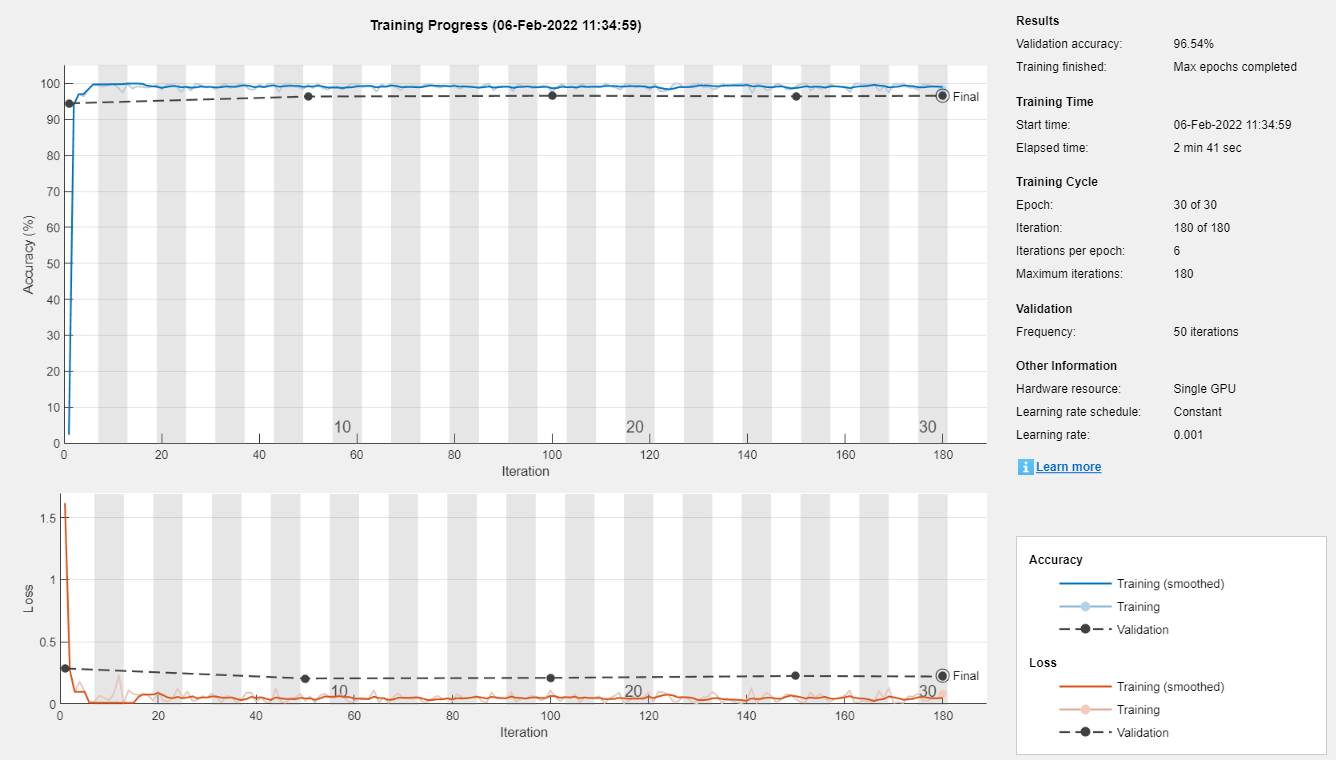

%Train Network 
%Train the network using the specified options and training data.
[net, traininfo] = trainNetwork(trainData(:,1),trainData(:,2),lgraph,opts);

%To plot confusion matrix 
pred = classify(net,testData(:,1)) 

pred = 864×1 cell array
    {[No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No    No  

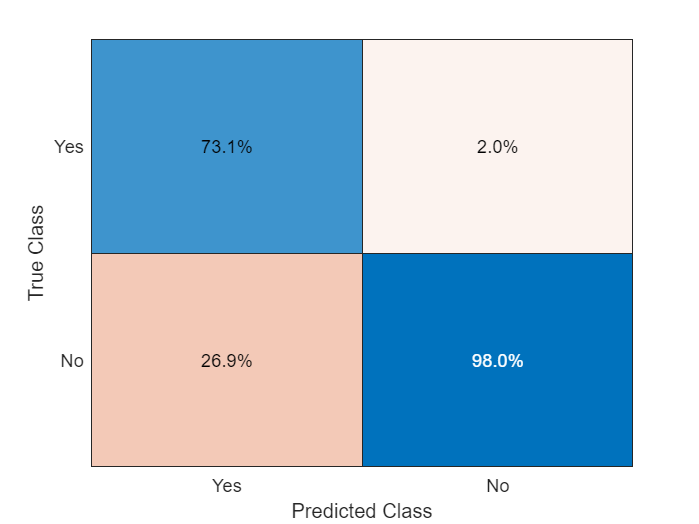

z=vertcat(pred{:,1}); 
q=vertcat(testData{:,2}); 
q=q(:); 
z=z(:); 
confusionchart(q(:),z(:),'Normalization','column-normalized'); 

function outputCell = getmask(inputCell) 
%GETMASK Convert region labels to a mask of labels of size equal to the
%size of the input signal.
% inputCell is a two-element cell array containing an ECG signal vector
% and a table of region labels. 
% outputCell is a two-element cell array containing the ECG signal vector
% and a categorical label vector mask of the same length as the signal. 
% Copyright 2020 The MathWorks, Inc.
sig = inputCell{1}; 
roiTable = inputCell{2}; 
L = length(sig); 
M = signalMask(roiTable); 
% Get categorical mask and give priority to QRS regions when there is overlap
mask = catmask(M,L); 
% Set missing values to "No"
mask(ismissing(mask)) = "No"; 
outputCell = {sig,mask}; 
end
function outputCell = resizeData(inputCell) 
%RESIZEDATA Break input signal and label mask into segments of length
%1000.
%
% inputCell is a two-element cell array containing a signal and a
% label mask.
%
% outputCell is a two-column cell array containing as many 5000-long
% signal segments and label masks that were possible to generate from the
% input data.
% Copyright 2019 The MathWorks, Inc.
 targetLength = 1000; 
 sig = inputCell{1}; 
 mask = inputCell{2}; 
 % Get number of chunks
 numChunks = floor(size(sig,1)/targetLength); 
 % Truncate signal and mask to integer number of chunks
 sig = sig(1:numChunks*targetLength); 
 mask = mask(1:numChunks*targetLength); 
 % Create a cell array containing signal chunks
 sigOut = reshape(sig,targetLength,numChunks)'; 
 sigOut = num2cell(sigOut,2); 
 % Create a cell array containing mask chunks
 lblOut = reshape(mask,targetLength,numChunks)'; 
 lblOut = num2cell(lblOut,2); 
 % Output a two-column cell array with all chunks
 outputCell = [sigOut, lblOut]; 
end
